## Definizione parametri

%% PARAMETERS
rtlsdr_id        = '0';                                             % stick ID
rtlsdr_fc        = 103.e6;                                          % tuner centre frequency in Hz
rtlsdr_fs        = 228e3;                                           % tuner sampling rate (fixed to 228 kHz)
rtlsdr_frmlen    = 1000*38;                                           % output data frame size (must be a multiple of 5)
rtlsdr_gain      = 50;                                              % tuner gain in dB
rtlsdr_datatype  = 'double';                                        % output data type
audio_fs         = 48e3;                                            % audio output sampling rate
simTime          = 30;                                              % simulation time in seconds
freqDev          = 75e3;
numSampleSim     = simTime*rtlsdr_fs;

sdrOn = 1;

## Filtri

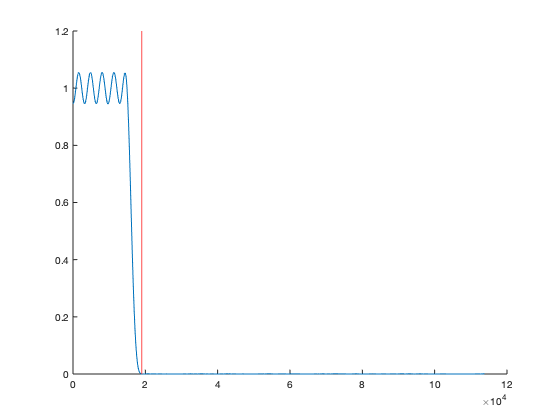

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 19000
            Color: [1 0 0]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties



%% ********** Filtri **********

    % carico i filtri da file esterni
    filtriMono

## Definisco oggetti di varie classi

% link to a physical rtl-sdr
if sdrOn == 1
obj_rtlsdr = comm.SDRRTLReceiver(...
    rtlsdr_id,...
    'CenterFrequency', rtlsdr_fc,...
    'EnableTunerAGC', false,...
    'TunerGain', rtlsdr_gain,...
    'SampleRate', rtlsdr_fs, ...
    'SamplesPerFrame', rtlsdr_frmlen,...
    'OutputDataType', rtlsdr_datatype);
else
    load dumpFM
end

% ricampiona il segnale convertendo il rate da 228 kHz a 48 kHz
sampRateAd = dsp.SampleRateConverter('Bandwidth',15e3, ...
    'InputSampleRate',rtlsdr_fs,'OutputSampleRate',audio_fs, ...
    'StopbandAttenuation',50);

% spectrum analyzer a 228kHz
obj_spectrumUp = dsp.SpectrumAnalyzer(...
    'Name', 'Spectrum Analyzer 1',...
    'Title', 'Spettro del segnale ricevuto e toni di frequenza',...
    'SpectrumType', 'Power density',...
    'FrequencySpan', 'Full',...
    'ShowLegend', true,...
    'SampleRate', rtlsdr_fs,...
    'SpectralAverages', 100);

% spectrum analyzer banda audio
obj_spectrumAudio = dsp.SpectrumAnalyzer(...
    'Name', 'Spettro canali audio',...
    'Title', 'Audio Signal Spectrum',...
    'SpectrumType', 'Power density',...
    'FrequencySpan', 'Full',...
    'ShowLegend', true,...
    'SampleRate', audio_fs,...
    'SpectralAverages', 100);



% audio player
player = audioDeviceWriter('SampleRate',audio_fs);


## RICEVITORE

### Inizializzazione dei parametri della simulazione


% numero di campioni acquisiti
numSamp = 0;
muta = 0;
lastSample = 0;


### Inviluppo complesso segnale ricevuto


while numSamp < numSampleSim
    muta = muta+1;
    
    % leggo i dati dalla sdr
    if sdrOn == 1
        sigRx = step(obj_rtlsdr);
    else
        sigRx = dump(numSamp+1:numSamp+rtlsdr_frmlen);
    end
    
    tic

### Derivatore

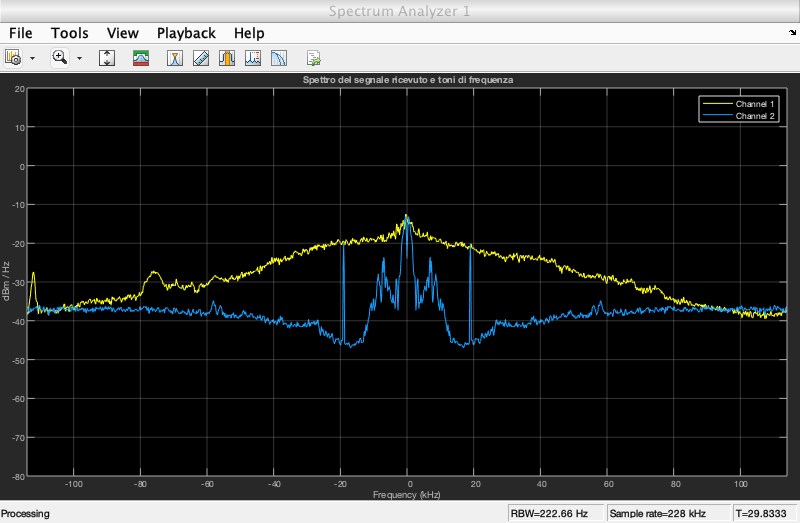

    % creo una versione ritardata di un campione del segnale ricevuto
    sigRxDel = [lastSample; sigRx(1:end-1,1)];
    
    % Estraggo il segnale modulante dall'inviluppo complesso del segnale
    % ricevuto
    rxData = rtlsdr_fs/(2*pi*freqDev)*angle(sigRx.* conj(sigRxDel));
    
    % spettro del segnale all'ingresso e all'uscita del derivatore
    step(obj_spectrumUp,[sigRx,rxData])

## Ricostruzione segnale    

#### Segnale L+R

    % Demodulo segnale BB
    LPRBBUp = step(obj_lpf,rxData);
    
    

## Segnale stereo in banda base

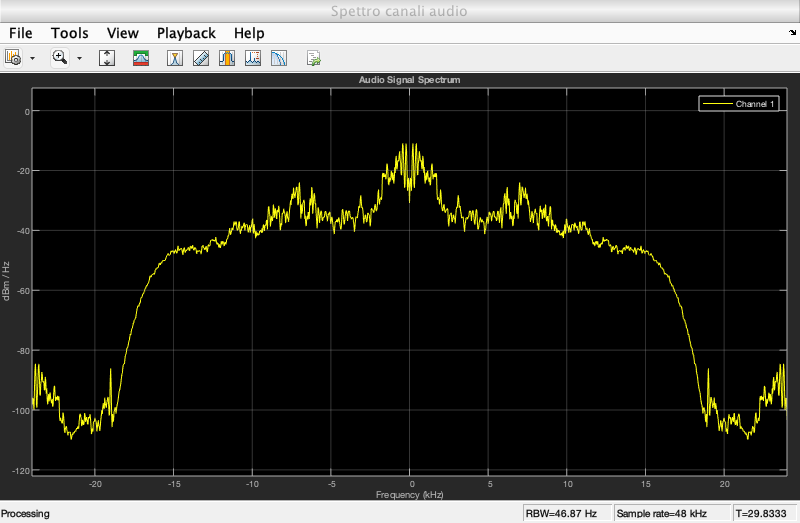

    % conversione di rate a 48 kHz
    LPRBB = sampRateAd(LPRBBUp);
    
    % spettro segnale audio
    step(obj_spectrumAudio,[LPRBB])

    
    % riproduco sequenza ricevuta
    play(player,[LPRBB]);
    
    % aggiorno il numero di campioni processati in uscita dalla rtlsdr
    numSamp = numSamp+rtlsdr_frmlen;
    
    lastSample = sigRx(end);
    elapsedTime(muta) = toc;
    
end
